clc; clear;

global m_ball g d_ball kappa bounces options d_becher_

bounces = 3;

y_0 = 30*10^-2;
l = 180*10^-2;
alpha_0 = 40;
v_w = 4.5;
v_0 = 2.8;
g = 9.81;
c_w = 0.47;
roh = 1.2;
s_becher = 1;
d_becher = 30;
h_becher = 8;
n_becher = 5;
d_ball = 50;
t_final = 30;

m_ball = 20;

refine = 10;

options = odeset('Events',@events,...
   'Refine',refine);


d = d_ball*10^-3;
A = pi*((d/2)^2);
kappa = (1/2)*roh*A*c_w;

global distances

d_becher_ = d_becher*10^-2;
h_becher_ = h_becher*10^-2;
s_becher_ = s_becher*10^-2;
d_0 = 0;
distances = [];
for i=1:n_becher
   distances = [distances,l+d_0];
   d_0 = d_0+d_becher_+s_becher_;
end


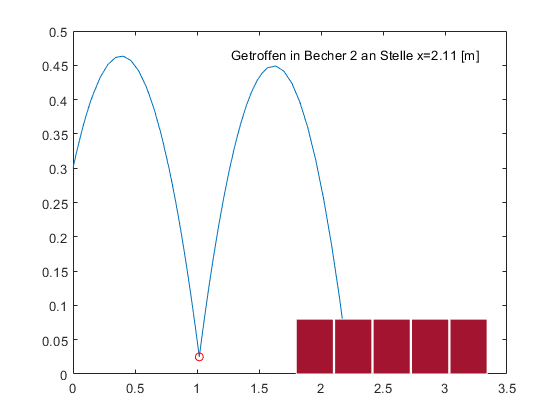

% Plot
[tout xout yout vout_x vout_y teout yeout ieout hit hit_becher] = bouncing_ball_fun(alpha_0,v_0,y_0,t_final);

plot(xout,yout)
hold on
plot(yeout(:,1),yeout(:,3),'ro')
for i=1:length(distances)
    rectangle('Position',[distances(i) 0 d_becher_ h_becher_],...
    "FaceColor",'#A2142F', "EdgeColor",'w')
end

if hit
    dim = [.4 .6 .3 .3];
    str = "Getroffen in Becher "+hit_becher+" an Stelle x="+distances(hit_becher)+" [m]";
    annotation('textbox',dim,'String',str,'FitBoxToText','on','EdgeColor','none');
end

hold off

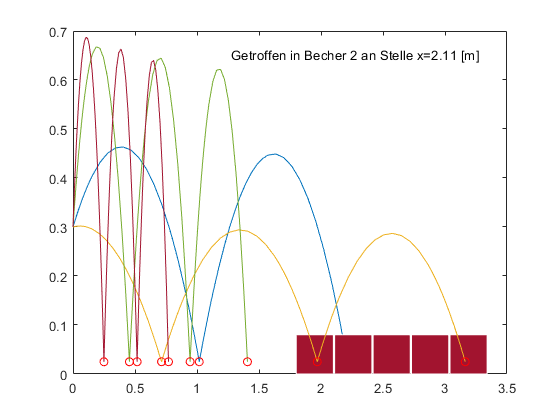

% Parameterstudie
alpha_p = randperm(89,3);
solutions = cell(length(alpha_p));
for i=1:length(alpha_p)
    [tout xout yout vout_x vout_y teout yeout ieout hit hit_becher]...
        = bouncing_ball_fun(alpha_p(i),v_0,y_0,t_final);
    solutions{i,1} = xout;
    solutions{i,2} = yout;
    solutions{i,3} = yeout;
    solutions{i,4} = hit;
    solutions{i,5} = hit_becher;
end

plot([],[])
hold on
for i=1:length(distances)
    rectangle('Position',[distances(i) 0 d_becher_ h_becher_],...
    "FaceColor",'#A2142F', "EdgeColor",'w')
end

for i=1:length(alpha_p)
    yeout_ = solutions{i,3};
    plot(solutions{i,1},solutions{i,2})
    plot(yeout_(:,1),yeout_(:,3),'ro')
end
hold off

function [tout xout yout vout_x vout_y teout yeout ieout hit hit_becher] = bouncing_ball_fun(alpha,v0,y0,t_final)
global bounces options distances d_becher_

% startposition x
x_old=0;
y_old = y0;

% startgeschwindigkeit
v_new_x=v0*cosd(alpha);
v_new_y=v0*sind(alpha);
t_start = 0;


tout = 0;
xout = [];
yout = [];
vout_x = [];
vout_y = [];
teout = [];
yeout = [];
ieout = [];
hit = [];
hit_becher = [];
for bounce=1:bounces
    
    [t,y,te,ye,ie] = ode45(@ball_bounce,[t_start t_final],[x_old v_new_x y_old v_new_y],options);
    
    tout = [tout; t];
    xout = [xout; y(:,1)];
    yout = [yout; y(:,3)];
    vout_x = [vout_x; y(2,:)];
    vout_y = [vout_y; y(4,:)];

    teout = [teout; te];          % Events at tstart are never reported.
    yeout = [yeout; ye];
    ieout = [ieout; ie];
    
    x_old = y(end,1);
    y_old = y(end,3);
    
    v_new_x = y(end,2);
    v_new_y = -y(end,4);
    
    % Überprüfe ob einer der Becher getroffen wurde
    if x_old>distances(bounce) && x_old<distances(bounce)+d_becher_
        hit=[hit; true];
        hit_becher=[hit_becher; bounce];
        break
    end

end

end

function dvdt = ball_bounce(t,v)
% Globale Variablen aus der Deklaration und Initialisierung
global m_ball g kappa
% v(1) ... x
% v(2) ... xpunkt
% v(3) ... y
% v(4) ... ypunkt

% Dragforce allgemein
F_drag_ = kappa*sqrt(v(2)^2+v(4)^2);

% Rechte und linke Seiten der Differentialgleichungen
dvdt = [v(2);-F_drag_*v(2)/(m_ball*10^-3);v(4);-F_drag_*v(4)/(m_ball*10^-3)-g];
end


function [value,isterminal,direction] = events(t,y)
global d_ball
d = d_ball*10^-3;

value = y(3)-d/2;     % detect height = 0

isterminal = 1;   % stop the integration
direction = -1;   % negative direction
end